`In the name of God`

# Blind Source Separation

# Homework #13

**Ashkan Jafari**

**810197483**

## Loading

load('hw13.mat');

L = 100;
K = 5;

## 1) 

### A) Plot

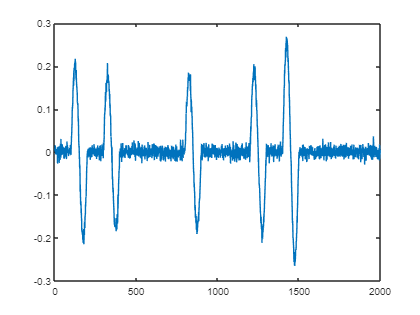

figure
plot(x1)

### B) Deconvolution

T = length(x1);
iterations = 50;
[s_hat,psi] = Deconvolve(x1,T,L,K,iterations);

**The convolution of estimated spike and estimated impluse train should be like x1(t).**

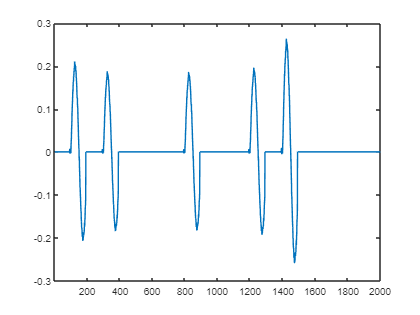

figure
plot(conv(s_hat,psi)) 
xlim([1,T])

figure
plot(x1)

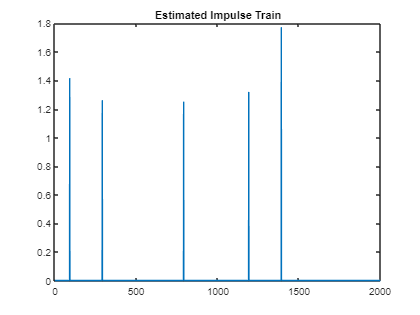

figure
plot(psi)
title('Estimated Impulse Train')

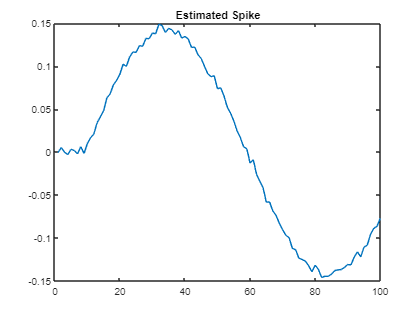

figure
plot(s_hat)
title('Estimated Spike')

## 2)

### A) Plot

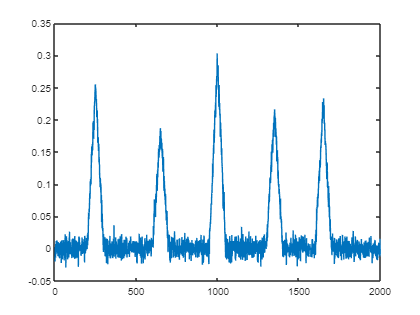

figure
plot(x2)

### B) Deconvolution

T = length(x2);
iterations = 100;
[s_hat,psi] = Deconvolve(x2,T,L,K,iterations);

figure
plot(x2)

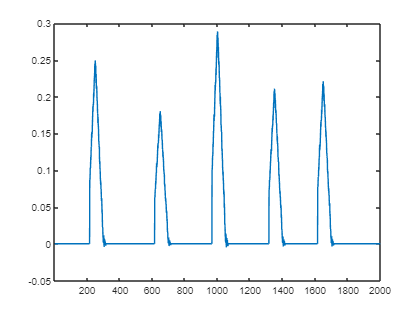

figure
plot(conv(s_hat,psi))
xlim([1,T])

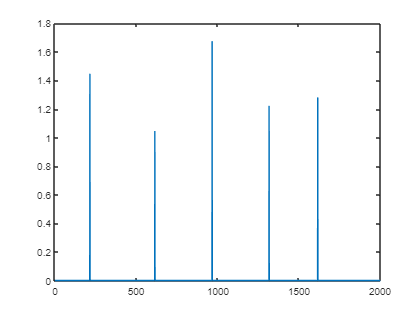

figure
plot(psi)

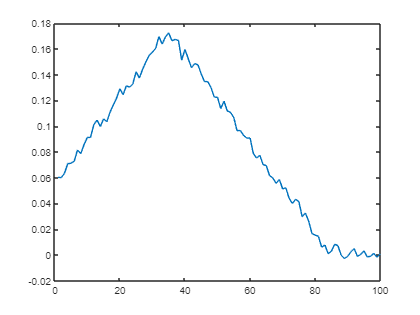


figure
plot(s_hat)

## 3)

### A) Plot

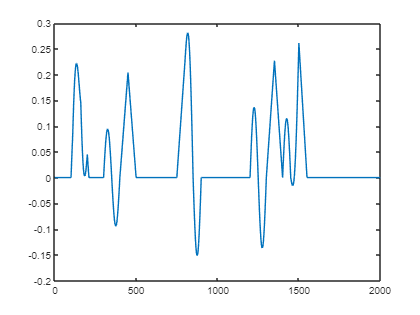

figure
plot(X(1,:))

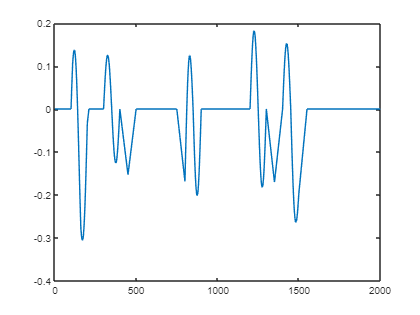

figure
plot(X(2,:))

### B) Deconvolution

% initialize A
A = rand(2);
for col = 1:2
    A(:,col) = A(:,col)/norm(A(:,col));
end

iters = 15;
e = 0;
[s_hat1_T,s_hat2_T,S_hat_3T] = Multi_deconvolve(A,X,L,K,iters,e);
X_hat = A*S_hat_3T;

figure
plot(X(1,:))

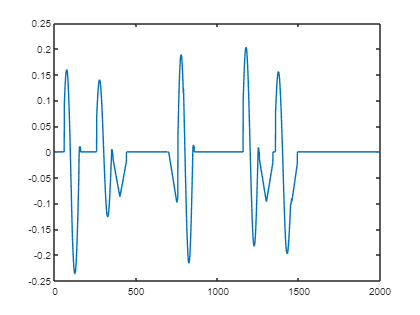

figure
plot(X_hat(1,:))

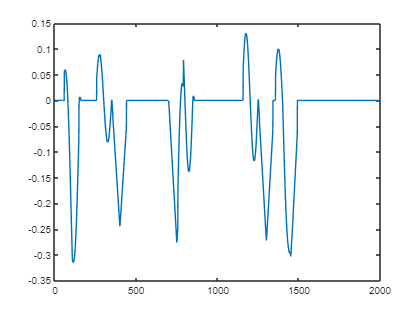

figure
plot(X_hat(2,:))

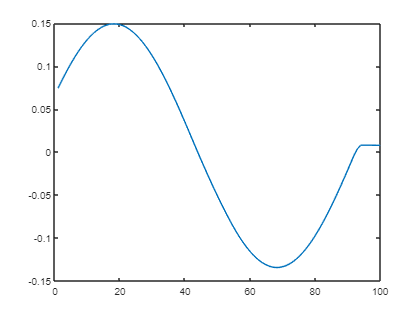

figure
plot(s_hat1_T)

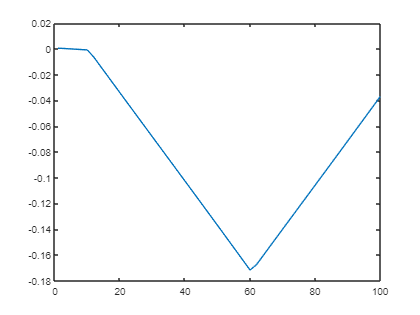

figure
plot(s_hat2_T)

## Functions.

function [s_hat,psi] = Deconvolve(x,T,L,K,iters)

% initialize psi
tau = randi([1 T-L],1,K);

% |taui - tauj| > L
alpha = rand(1,K);
psi = zeros(1,T);

Y = zeros(L,K);
for i = 1:length(tau)
    psi(tau(i)) = alpha(i);
    Y(:,i) = (x(tau(i):tau(i)+L-1));
end

e = 0;
for iter = 1:iters

    % psi is fixed
    for i = 1:length(tau)
        psi(tau(i)) = alpha(i);
        Y(:,i) = x(tau(i):tau(i)+L-1);
    end
 
    s_hat_ = Y*pinv(alpha);
    if norm(s_hat_) ~= 0
        s_hat = s_hat_/norm(s_hat_);
    else
        s_hat = s_hat_;
    end
   
    if norm(norm(x-conv(psi,s_hat,'same'))-e) < 1e-02
        break;
    end
    e = norm(x-conv(psi,s_hat,'same'));
    
    % s is fixed
    Z = zeros(L,T-(L-1));
    for i = 1:T-(L-1)
        Z(:,i) = x(i:i+L-1);
    end
   
    b = zeros(1,T-(L-1));
    for n = 1:K
        C = s_hat'*Z;
        [val,ind] = max(abs(C));
     
        b(ind) = val;
   
        Z_r = Z(:,max(1,ind-(L-1)):min(size(Z,2),ind+(L-1)));
        Z(:,max(1,ind-(L-1)):min(size(Z,2),ind+(L-1))) = zeros(size(Z_r));
    end
   
    psi = [b,zeros(1,L-1)];
    alpha = zeros(1,K);
   
    i = 1;
    for j = 1:length(psi)
        if psi(j) ~= 0
            alpha(i) = psi(j);
            tau(i) = j;
            i = i+1;
        end
    end
end
end

function [s_hat1_T,s_hat2_T,B] = Multi_deconvolve(A,X,L,K,iters,e)

for iter = 1:iters
    % A is fixed
    B = A\X;
    
    % Blind Deconvolution
    T = size(B,2);
    [s_hat1_T,psi1_T] = Deconvolve(B(1,:),T,L,K,iters);
    [s_hat2_T,psi2_T] = Deconvolve(B(2,:),T,L,K,iters);
    
    B = [conv(psi1_T,s_hat1_T,'same');conv(psi2_T,s_hat2_T,'same')];
    
    % S is fixed
    A = X*pinv(B);
    for col = 1:2
        A(:,col) = A(:,col)/norm(A(:,col));
    end
    
    if norm(norm(X-A*B),e) < 1e-02
        break;
    end
    e = norm(X-A*B);
end

end